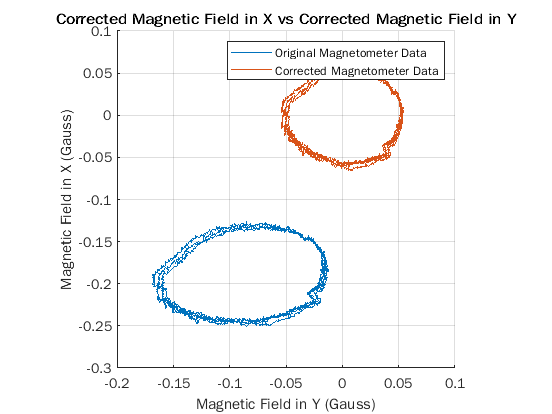

%%% Robot Sensing and Navigation: Lab4 (Analysis Scripts) %%%

%{
data = rosbag("driving_data_nuance.bag");

% Loading the GPS Data #####################################################
gps = select(data, "Topic", "gps");
msgs = readMessages(gps,"DataFormat","struct");

s_seq = cellfun(@(m) double(m.Header.Seq),msgs);
s_Latitude = cellfun(@(m) double(m.Latitude),msgs);
s_Longitude = cellfun(@(m) double(m.Longitude),msgs);
s_Altitude = cellfun(@(m) double(m.Altitude),msgs);
s_UTMEasting = cellfun(@(m) double(m.UTMEasting),msgs);
s_UTMNorthing = cellfun(@(m) double(m.UTMNorthing),msgs);
easting = cellfun(@(m) double(m.UTMEasting),msgs);
northing = cellfun(@(m) double(m.UTMNorthing),msgs);
s_Zone = cellfun(@(m) double(m.Zone),msgs);
s_Letter = cellfun(@(m) double(m.Letter),msgs);

s_UTMEastingScaled = s_UTMEasting - min(s_UTMEasting);
s_UTMNorthingScaled = s_UTMNorthing - min(s_UTMNorthing);

% Loading the IMU Data #####################################################
imu = select(data, "Topic", "imu/imu_data");
mag = select(data, "Topic", "imu/magnetic_data");
imu_msgs = readMessages(imu,"DataFormat","struct");
mag_msgs = readMessages(mag,"DataFormat","struct");
% imu_msgs{1}
% mag_msgs{1}

imu_seq = cellfun(@(m) double(m.Header.Seq),imu_msgs);
imu_qx = cellfun(@(m) double(m.Orientation.X),imu_msgs);
imu_qy = cellfun(@(m) double(m.Orientation.Y),imu_msgs);
imu_qz = cellfun(@(m) double(m.Orientation.Z),imu_msgs);
imu_qw = cellfun(@(m) double(m.Orientation.W),imu_msgs);
imu_gx = cellfun(@(m) double(m.AngularVelocity.X),imu_msgs);
imu_gy = cellfun(@(m) double(m.AngularVelocity.Y),imu_msgs);
imu_gz = cellfun(@(m) double(m.AngularVelocity.Z),imu_msgs);
imu_ax = cellfun(@(m) double(m.LinearAcceleration.X),imu_msgs);
imu_ay = cellfun(@(m) double(m.LinearAcceleration.Y),imu_msgs);
imu_az = cellfun(@(m) double(m.LinearAcceleration.Z),imu_msgs);

imu_seq(end, :) = [];
imu_qx(end, :) = [];
imu_qy(end, :) = [];
imu_qz(end, :) = [];
imu_qw(end, :) = [];
imu_gx(end, :) = [];
imu_gy(end, :) = [];
imu_gz(end, :) = [];
imu_ax(end, :) = [];
imu_ay(end, :) = [];
imu_az(end, :) = [];

mag_seq = cellfun(@(m) double(m.Header.Seq),mag_msgs);
mag_x = cellfun(@(m) double(m.MagneticField_.X),mag_msgs);
mag_y = cellfun(@(m) double(m.MagneticField_.Y),mag_msgs);
mag_z = cellfun(@(m) double(m.MagneticField_.Z),mag_msgs);

% Getting Roll Pitch Yaw values from the quaternion data:
yaw = zeros(size(imu_seq));
pitch = zeros(size(imu_seq));
roll = zeros(size(imu_seq));

for i = 1:size(imu_seq)
    [roll(i), pitch(i), yaw(i)] = quat2angle([imu_qx(i) imu_qy(i) imu_qz(i) imu_qw(i)]);
end

%}

% Extract the ruggles circle portion of magnetometer data:
magX=mag_x(7520:10000);
magY=mag_y(7520:10000);
magXY=[magX magY];

A = EllipseDirectFit(magXY);
a=A(1);
b=A(2);
c=A(3);
d=A(4);
e=A(5);
f=A(6);

% Plot of the ruggles circle portion of magnetic field
%plot(mag_x(7520:10000), mag_y(7520:10000));
%grid on
%title("Magnetic Field in X vs Magnetic Field in Y");

% Defining Bank Angle and Elevation Angle
bank_angle = atan(mean(imu_ay(5000:7000))/(mean(imu_az(5000:7000))));
elev_angle  = atan(mean(imu_ax(5000:7000))/(mean(imu_az(5000:7000))));

%%%%%%%%%%%%% Compensation for Elevation angle and Bank Angle %%%%%%%

% Rotation Matrix for Tilt Correction
rot_tilt_correction = [cos(elev_angle) 0 -sin(elev_angle);
    sin(bank_angle)*sin(elev_angle) cos(bank_angle) sin(bank_angle)*cos(elev_angle);
    cos(bank_angle)*sin(elev_angle) -sin(bank_angle) cos(bank_angle)*cos(elev_angle)];

% For loop to compute Magnetic Field in X, Y and Z direction for tilt
% correction
for i = 1:length(mag_x)
magXYZ_tilt_correction = rot_tilt_correction*[mag_x(i) ; mag_y(i) ; mag_z(i)];
magX_tilt_correction(i,1) = magXYZ_tilt_correction(1);
magY_tilt_correction(i,1) = magXYZ_tilt_correction(2);
magZ_tilt_correction(i,1) = magXYZ_tilt_correction(3);
end

%%%%%%%%%%% Determine Hard Iron Offset %%%%%%%%%%%%%%%:
% HIOffset = mean(magXY);
% magX_corrected_hard = mag_x - HIOffset(1);
% magY_corrected_hard = mag_y - HIOffset(2);
offset_x = (max(magX_tilt_correction(7520:10000))+min(magX_tilt_correction(7520:10000)))/2;
offset_y = (max(magY_tilt_correction(7520:10000))+min(magY_tilt_correction(7520:10000)))/2;
offset_z = (max(magZ_tilt_correction(7520:10000))+min(magZ_tilt_correction(7520:10000)))/2;

magX_corrected_hard = magX_tilt_correction - offset_x;
magY_corrected_hard = magY_tilt_correction - offset_y;
magZ_corrected_hard = magZ_tilt_correction - offset_z;

%%%%%%%%%%%%%%%%%%%%%% Soft Iron Correction %%%%%%%%%%%%%%%%%

% Make Rotation Matrix for Soft Iron Compensation:
theta = -1/2*atan(b/(c-a));
rot_mat = [cos(theta) sin(theta); -sin(theta) cos(theta)];

magX_corrected = zeros(length(mag_x), 1);
magY_corrected = zeros(length(mag_y), 1);

for i = 1:length(mag_x)
    H = [magX_corrected_hard(i) ; magY_corrected_hard(i)];
    magXY_soft_correction = rot_mat*H;
    magX_corrected(i) = 0.69*magXY_soft_correction(1);
    magY_corrected(i) = magXY_soft_correction(2);
end

% Plot of Corrected Magnetic Field:
figure();
hold on
grid on
plot(mag_x(7520:10000), mag_y(7520:10000));
plot(magX_corrected(7520:10000), magY_corrected(7520:10000));
legend("Original Magnetometer Data", "Corrected Magnetometer Data");
axis square
title("Corrected Magnetic Field in X vs Corrected Magnetic Field in Y")
xlabel('Magnetic Field in Y (Gauss)')
ylabel('Magnetic Field in X (Gauss)')
hold off

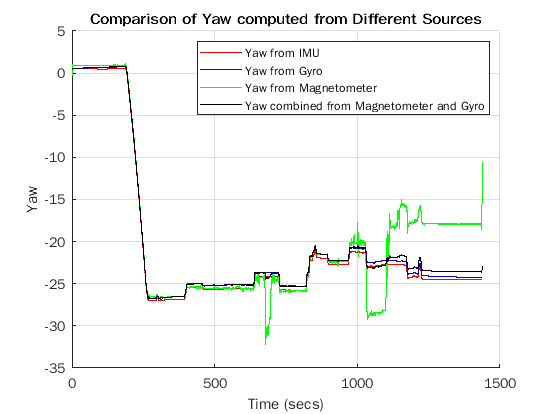


% Yaw from IMU
yaw_unwrapped = unwrap(yaw);

%%%%%%%%% Yaw From Magnetometer %%%%%%%%%%%%%%
yaw_mag = atan2(-magY_corrected, magX_corrected);
%yaw_mag_unwrapped = unwrap(yaw_mag);

yaw_mag = unwrap(yaw_mag);
yaw_mag_lowpass = lowpass(yaw_mag, 0.001, 40);

%yaw_mag_scaled = yaw_mag_unwrapped + 1.8*yaw_unwrapped(1);
yaw_mag_scaled = yaw_mag_lowpass - 3.5*yaw_unwrapped(1);
yaw_mag_filtered = yaw_mag_scaled;

%%%%%%%%%%%% Yaw From Gyro %%%%%%%%%%%%%%
yaw_gyro = (1/40)*cumtrapz(double(imu_seq), imu_gz);
yaw_gyro_scaled = yaw_gyro + 1.0*yaw_unwrapped(1);

% Yaw values comparsion
%figure();
%hold on
%plot(imu_seq, yaw_unwrapped,"r")
%plot(mag_seq,yaw_mag_scaled,"y")
%plot(imu_seq, yaw_gyro_scaled, "b")
%legend("Yaw", "Yaw from Magnetometer", "Yaw from Gyro")
%hold off

%%%%%%%%%%%%%%%% Filtering %%%%%%%%%%%%%%%%

% Yaw from magnetometer is already filtered %

tau = 0.000000009573;
alpha = tau/(tau+0.069);

yaw_gyro_filtered(1,1) = yaw_gyro_scaled(1,1);

for n = 2 : length(yaw_gyro_scaled)
    yaw_gyro_filtered(n, 1) = (1 - alpha)*yaw_gyro_filtered(n-1, 1) + (1 - alpha)*(yaw_gyro_scaled(n,1) - yaw_gyro_scaled(n-1,1));
end

% Plot comparison of yaw from gyro filtered and scaled
%figure();
%hold on
%plot(imu_seq, yaw_gyro_filtered, 'DisplayName', 'Yaw from Gyro Filtered', 'Color', 'r')
%plot(imu_seq, yaw_gyro_scaled, 'DisplayName', 'Yaw from Gyro Unfiltered', 'Color', 'b')
%legend
%hold off

bias = 0.1;

yaw_final = bias*yaw_mag_filtered + (1-bias)*yaw_gyro_filtered;

% Plot of processed Yaw Angles
figure();
hold on
grid on
plot(imu_seq/40, yaw_unwrapped, 'DisplayName','Yaw from IMU','Color','red')
plot(imu_seq/40, yaw_gyro_filtered, 'DisplayName','Yaw from Gyro','Color','blue')
plot(mag_seq/40, yaw_mag_filtered, 'DisplayName','Yaw from Magnetometer','Color','green')
plot(imu_seq/40, yaw_final, 'DisplayName','Yaw combined from Magnetometer and Gyro','Color','black')
title('Comparison of Yaw computed from Different Sources')
xlabel('Time (secs)')
ylabel('Yaw')
legend
hold off

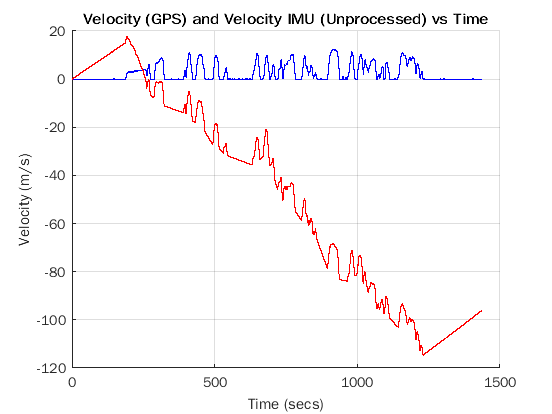


%%%%%%% Velocity from GPS %%%%%%%%%%%%

dt = 1;

velocity_gps = zeros(length(imu_seq), 1);
velocity_gps(1, 1) = 0;
for i = 2:length(easting)
    delta_easting = (easting(i) - easting(i-1));
    delta_northing = (northing(i)- northing(i-1));
    delta(i) = sqrt(delta_easting^2 + delta_northing^2);
end

for i = 1:length(northing)
    for j = 1:40
        velocity_gps(40*(i-1) + j) = delta(i);
    end
end

%%%%%%%%%%%%%%%% Velocity from Accelerometer Without Processing %%%%%%%%%
imu_vel_raw(1,1) = 0;

for i = 2:length(imu_seq)
    imu_vel_raw(i, 1) = imu_vel_raw(i-1,1) + imu_ax(i,1)/40;
end

% Plot of GPS and IMU velocity before the accelrometer data is processed
figure();
hold on
grid on
plot(imu_seq/40,velocity_gps, 'DisplayName', 'Velocity from GPS Data', 'Color', 'blue')
plot(imu_seq/40, imu_vel_raw, 'DisplayName', 'Velocity from Raw Accelerometer Data', 'Color', 'red')
title('Velocity (GPS) and Velocity IMU (Unprocessed) vs Time')
xlabel('Time (secs)')
ylabel('Velocity (m/s)')
hold off

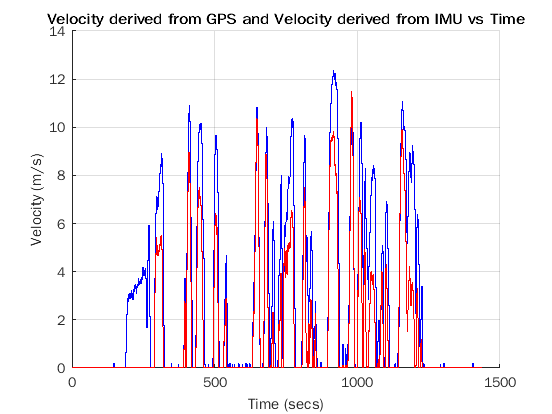


%%%%%%%%%%% Velocity from Accelerometer Data %%%%%%%%%%%

imu_ax_filtered = imu_ax;
imu_ax_filtered(1:11370) = 0;
imu_ax_filtered(12990:15570) = 0 - mean(imu_ax_filtered(11370:12990));
imu_ax_filtered(16975:17215) = 0 - mean(imu_ax_filtered(15570:16975));
imu_ax_filtered(18650:19665) = 0 - mean(imu_ax_filtered(17215:18650));
imu_ax_filtered(20700:21170) = 0 - mean(imu_ax_filtered(19665:20700));
imu_ax_filtered(21870:25190) = 0 - mean(imu_ax_filtered(21170:21870));
imu_ax_filtered(26380:26625) = 0 - mean(imu_ax_filtered(25190:26380));
imu_ax_filtered(28550:28745) = 0 - mean(imu_ax_filtered(26625:28550));
imu_ax_filtered(31360:32120) = 0 - mean(imu_ax_filtered(28745:31360));
imu_ax_filtered(34390:34815) = 0 - mean(imu_ax_filtered(32120:34390));
imu_ax_filtered(35150:35675) = 0 - mean(imu_ax_filtered(34815:35150));
imu_ax_filtered(37545:38515) = 0 - mean(imu_ax_filtered(35675:37545));
imu_ax_filtered(39700:39835) = 0 - mean(imu_ax_filtered(38515:39700));
imu_ax_filtered(42705:42785) = 0 - mean(imu_ax_filtered(39835:42705));
imu_ax_filtered(43710:43775) = 0 - mean(imu_ax_filtered(42785:43710));
imu_ax_filtered(44550:45585) = 0 - mean(imu_ax_filtered(43775:44550));
imu_ax_filtered(49260:end) = 0;

imu_vel_filtered(1,1) = 0;

mean(imu_ax_filtered);
max(imu_ax_filtered);
min(imu_ax_filtered);

imu_vel_filtered(1,1) = 0;

for i = 2:length(imu_seq)
    imu_vel_filtered(i, 1) = imu_vel_filtered(i-1,1) + imu_ax_filtered(i,1)/40;
    if imu_vel_filtered(i, 1) < 0 || velocity_gps(i) <= 0.5
        imu_vel_filtered(i, 1) = 0;
    end
end

figure();
hold on
grid on
plot(imu_seq/40,velocity_gps, 'DisplayName', 'Velocity from GPS Data', 'Color', 'blue')
plot(imu_seq/40, imu_vel_filtered, 'DisplayName', 'Velocity from IMU Data', 'Color', 'red')
title('Velocity derived from GPS and Velocity derived from IMU vs Time')
xlabel('Time (secs)')
ylabel('Velocity (m/s)')
hold off

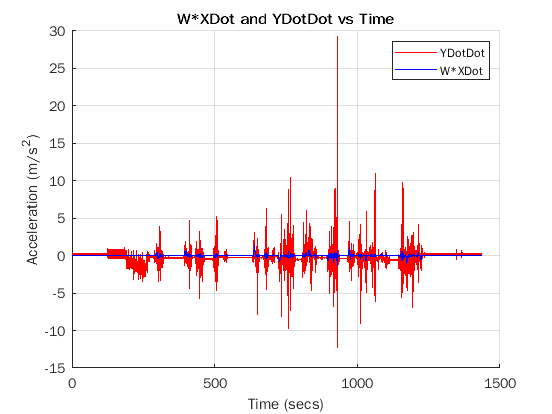


% Calculating WX Dot and Y Double Dot

wx_dot = imu_gz.*imu_vel_filtered;

figure();
title('W*XDot and YDotDot vs Time')
xlabel('Time (secs)')
ylabel('Acceleration (m/s^2)')
grid on
legend
hold on
plot(imu_seq/40,imu_ay,'DisplayName','YDotDot','Color','red')
plot(imu_seq/40, wx_dot, 'DisplayName', 'W*XDot', 'Color', 'blue')
hold off


%%%%%%%%%%%%%%%% Dead Recknoning %%%%%%%%%%%%%%%%%%

% Plotting displacement data from GPS and IMU

% Computing distance from velocity of IMU data (Integration)
imu_distance = cumtrapz(imu_seq, imu_vel_filtered);

imu_x_coordinates(1,1) = 0;
imu_y_coordinates(1,1) = 0;
displacement_angle = 140*pi/180;
angle_final = yaw_final + displacement_angle;

for i = 2:length(yaw_mag_filtered) 
      imu_x_coordinates(i,1) = imu_x_coordinates(i-1,1) + (imu_distance(i) - imu_distance(i-1))*-cos(unwrap(angle_final(i)));
      imu_y_coordinates(i,1) = imu_y_coordinates(i-1,1) + (imu_distance(i) - imu_distance(i-1))*sin(unwrap(angle_final(i))); 
end 

% Offsetting the coordinates
imu_x_coordinates = imu_x_coordinates - imu_x_coordinates(1);
imu_y_coordinates = imu_y_coordinates - imu_y_coordinates(1);

% Scaling the coordinates in order to plot with the GPS data
imu_x_scaled = imu_x_coordinates*(0.043);
imu_y_scaled = imu_y_coordinates*(0.043);

% Computing W Dot
w_dot(1,1) = 0;
for i = 2:length(imu_gz)
    w_dot(i,1) = (imu_gz(i) - imu_gz(i-1))*40;
end

% Computing Xc
Xc = (imu_ay - wx_dot)./w_dot;

Xc_estimation = mean(Xc(13000:14000))

Xc_estimation = -1.1613

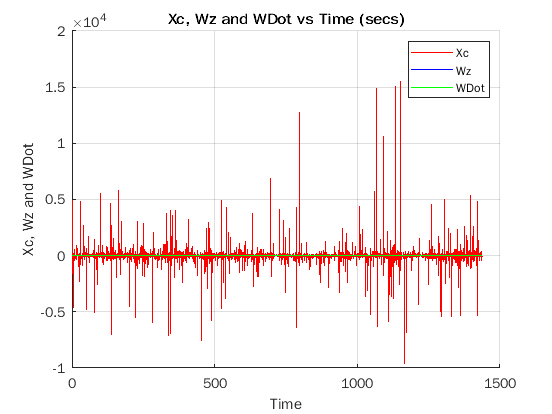

% With the help of given equations, the value of Xc is calculated to be
% -1.1613m. The value is consistent with the placement of inertial sensor.

figure();
hold on
title('Xc, Wz and WDot vs Time (secs)')
xlabel('Time')
ylabel('Xc, Wz and WDot')
grid on
legend
plot(imu_seq/40, Xc, 'DisplayName', 'Xc', 'Color', 'red')
plot(imu_seq/40, imu_gz, 'DisplayName', 'Wz', 'Color', 'blue')
plot(imu_seq/40, w_dot, 'DisplayName', 'WDot', 'Color', 'green')
hold off

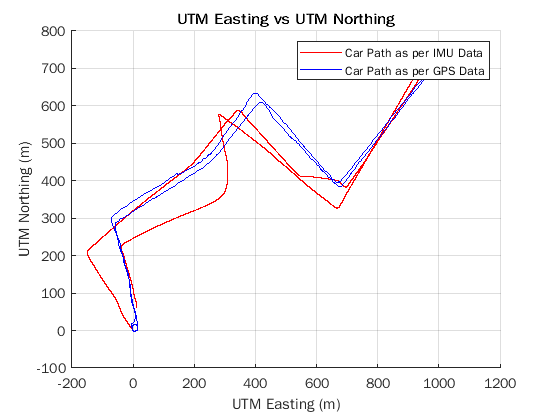

%}

% Plotting Displacement as per GPS Data:

easting = easting - easting(1);
northing = northing - northing(1);

figure();
hold on
plot(imu_x_scaled,imu_y_scaled,'DisplayName','Car Path as per IMU Data','Color','red')
plot(easting,northing,'DisplayName','Car Path as per GPS Data','Color','blue')
title('UTM Easting vs UTM Northing')
xlabel('UTM Easting (m)')
ylabel('UTM Northing (m)')
grid on
hold off
legend


%%%%%%%%%%%%%%%% GPS Plots %%%%%%%%%%%%%%%%%%%%%%

%{

figure();
scatter(s_UTMEastingScaled, s_UTMNorthingScaled, "filled", "r");
title("Stationary: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");

figure();
plot(s_UTMEastingScaled, s_UTMNorthingScaled);
grid on
title("Stationary: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");

figure();
geoplot(s_Latitude,s_Longitude,'-m.', 'MarkerSize',10)
geobasemap streets
title('Latitude & Longitude on a Map')

%}


function A = EllipseDirectFit(XY);
%
%  Direct ellipse fit, proposed in article
%    A. W. Fitzgibbon, M. Pilu, R. B. Fisher
%     "Direct Least Squares Fitting of Ellipses"
%     IEEE Trans. PAMI, Vol. 21, pages 476-480 (1999)
%
%  Our code is based on a numerically stable version
%  of this fit published by R. Halir and J. Flusser
%
%     Input:  XY(n,2) is the array of coordinates of n points x(i)=XY(i,1), y(i)=XY(i,2)
%
%     Output: A = [a b c d e f]' is the vector of algebraic 
%             parameters of the fitting ellipse:
%             ax^2 + bxy + cy^2 +dx + ey + f = 0
%             the vector A is normed, so that ||A||=1
%
%  This is a fast non-iterative ellipse fit.
%
%  It returns ellipses only, even if points are
%  better approximated by a hyperbola.
%  It is somewhat biased toward smaller ellipses.
%
centroid = mean(XY);   % the centroid of the data set
D1 = [(XY(:,1)-centroid(1)).^2, (XY(:,1)-centroid(1)).*(XY(:,2)-centroid(2)),...
      (XY(:,2)-centroid(2)).^2];
D2 = [XY(:,1)-centroid(1), XY(:,2)-centroid(2), ones(size(XY,1),1)];
S1 = D1'*D1;
S2 = D1'*D2;
S3 = D2'*D2;
T = -inv(S3)*S2';
M = S1 + S2*T;
M = [M(3,:)./2; -M(2,:); M(1,:)./2];
[evec,eval] = eig(M);
cond = 4*evec(1,:).*evec(3,:)-evec(2,:).^2;
A1 = evec(:,find(cond>0));
A = [A1; T*A1];
A4 = A(4)-2*A(1)*centroid(1)-A(2)*centroid(2);
A5 = A(5)-2*A(3)*centroid(2)-A(2)*centroid(1);
A6 = A(6)+A(1)*centroid(1)^2+A(3)*centroid(2)^2+...
     A(2)*centroid(1)*centroid(2)-A(4)*centroid(1)-A(5)*centroid(2);
A(4) = A4;  A(5) = A5;  A(6) = A6;
A = A/norm(A);
end  %  EllipseDirectFit